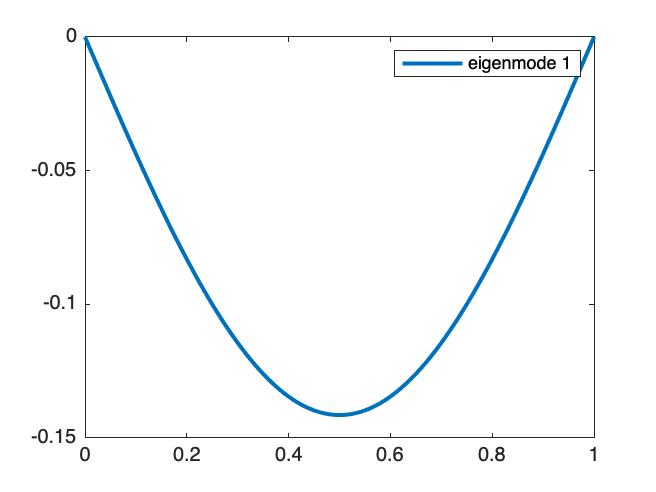

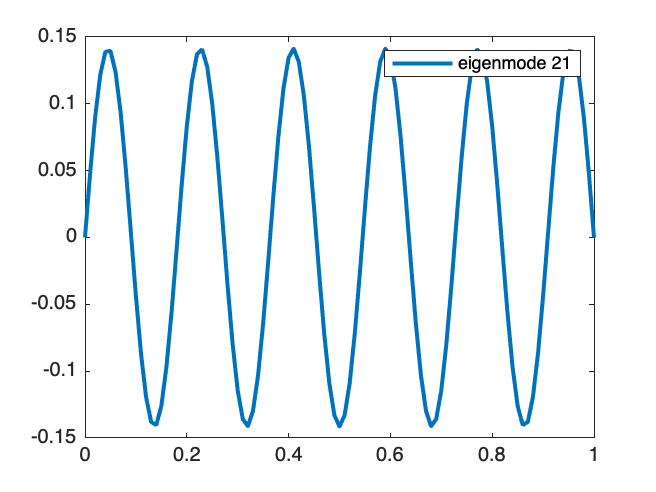

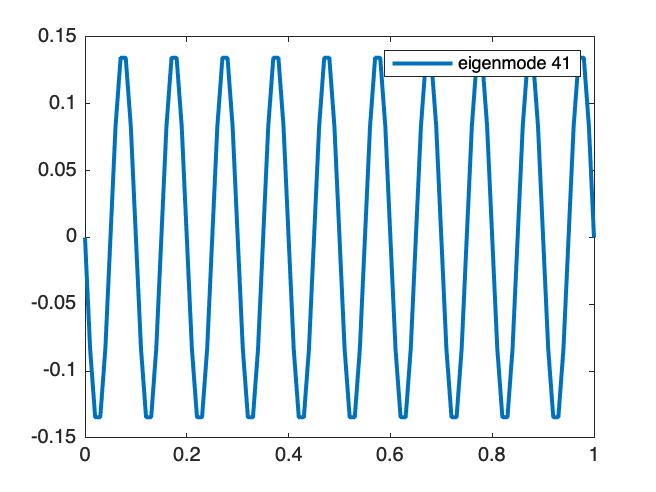

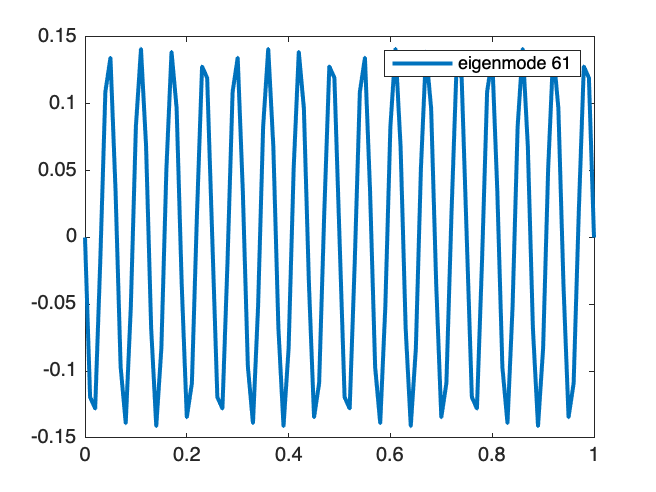

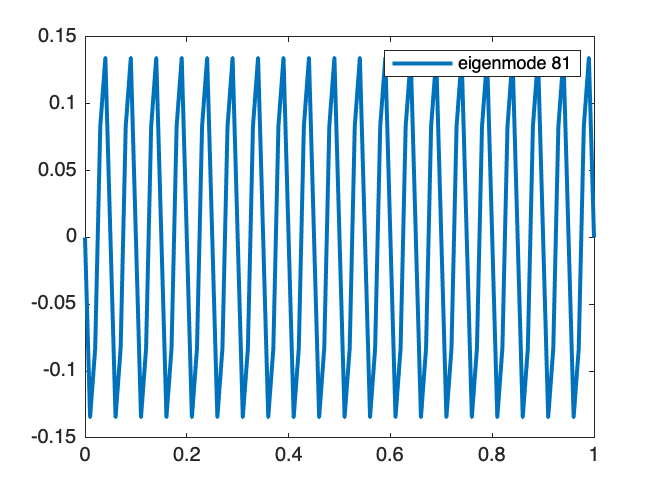

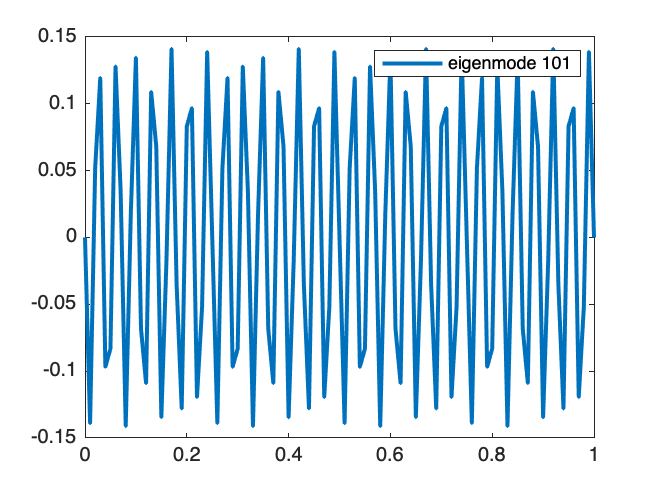

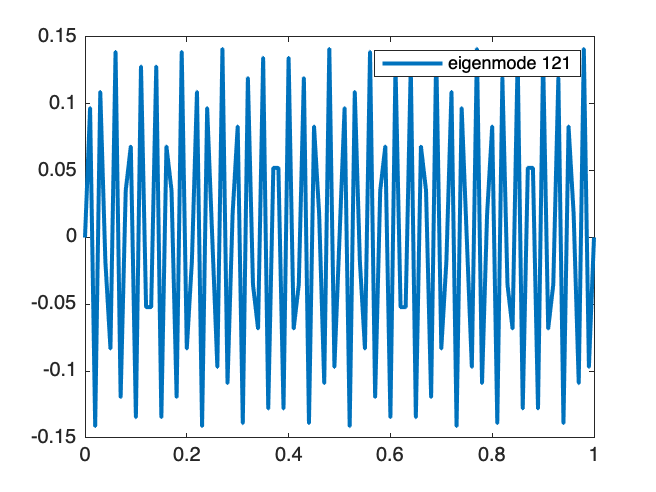

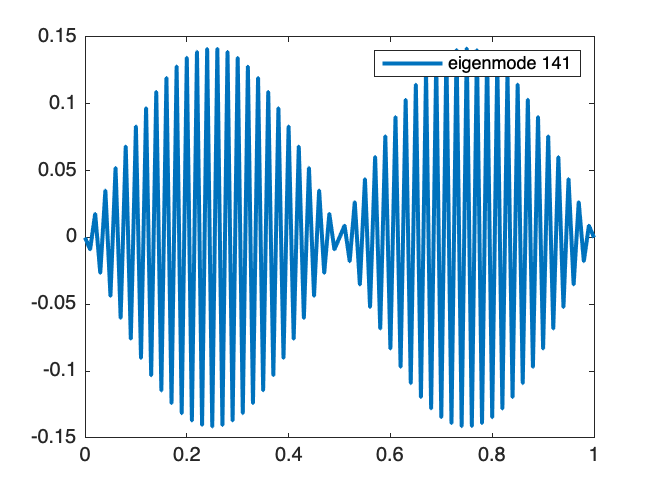

% simple example for 1D wave eqn discr. over N1 spaces
% assume N = N1-1 interior points
N1 = 100; 
c = 17;
h = 1/N1;

A = func_2der_diffmat(N1,c);
Z = zeros(N1-1);
I = eye(N1-1);

[X,L] = polyeig(I,Z,A);

dumvec = 0:h:1;

for i = 1:20:180
    figure(i)
    etitle = ['eigenmode ', num2str(i)];
    x = [0;X(:,i);0];
    plot(dumvec, x, LineWidth=2);
    legend(etitle)
    hold on
end

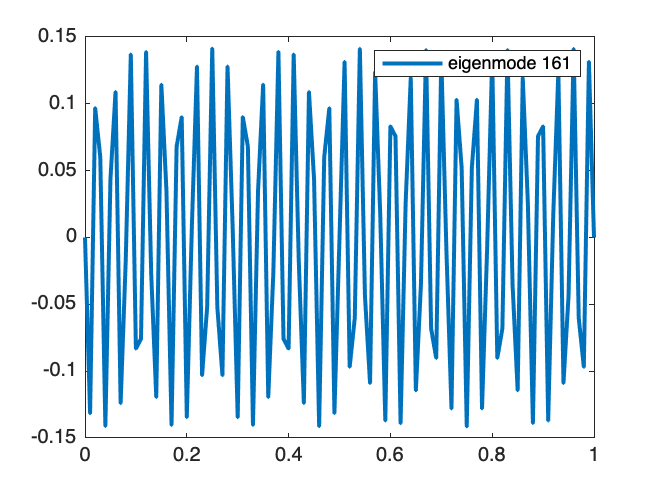

hold off


[Xeig, Eeig] = eig(A);

figure(10)
for i = (N1-3):(N1-1)
    plot(dumvec,[0;Xeig(:,i);0],LineWidth=2)
    ltitle = ['E-eigenmode',num2str(i)]
    legend(ltitle)
    hold on
end

ltitle = 'E-eigenmode97'

ltitle = 'E-eigenmode98'

ltitle = 'E-eigenmode99'

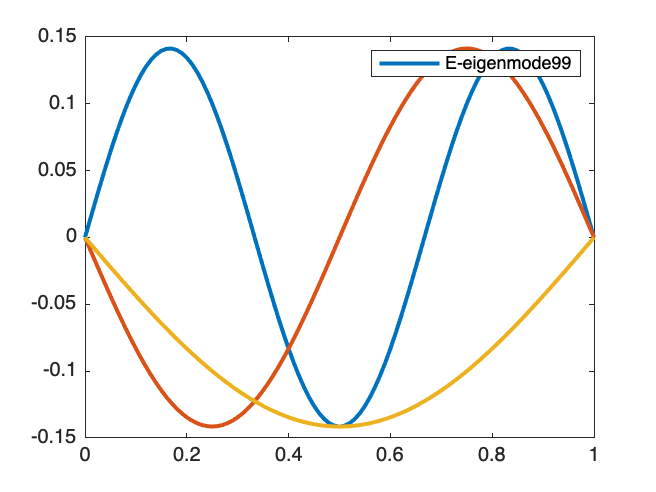

hold off